%load image
A = imread('lmu_small.png');

%reshape image for kmeans function
A = reshape(A,[16384,3]);

%cast rgb values to double for distance function to work properly
A = cast(A,'double')

A =     51   127   211
    52   128   212
    53   129   212
    53   129   214
    54   130   216
    55   131   217
    55   132   218
    54   134   219
    54   133   218
    55   134   219


num_data = 16384

r = 16384

c = 3

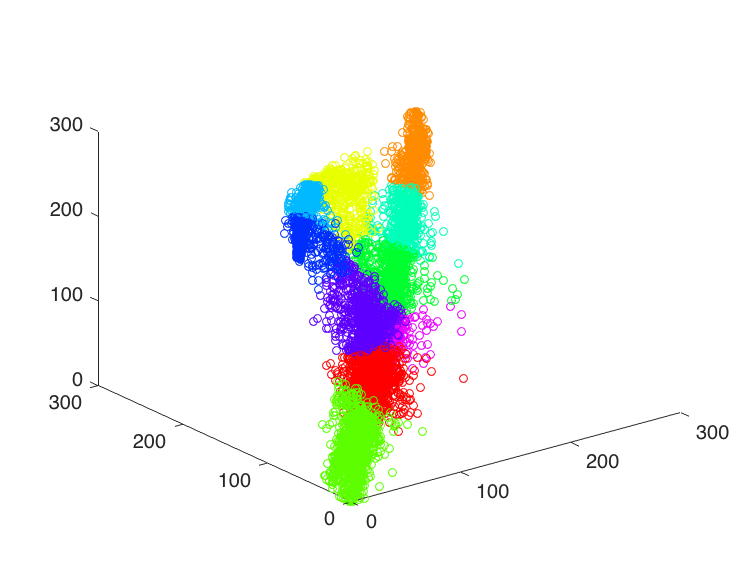


%call kmeans compute to get compressed colors
[means, clusters] = KMeansCompute(A,10,@pdists,10);


%generalize the collors to the means
for ii = 1:16384
A(ii,:) = means(clusters(ii),:);
end

%reshape back to original format
A = reshape(A,[128,128,3]);

%cast to original datatype
A = cast(A,'uint8')

A = 128×128×3 uint8 array
A(:,:,1) =

    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62   102    62   102    92    92   102   102    92    39    92    39    92    92    92
    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62 

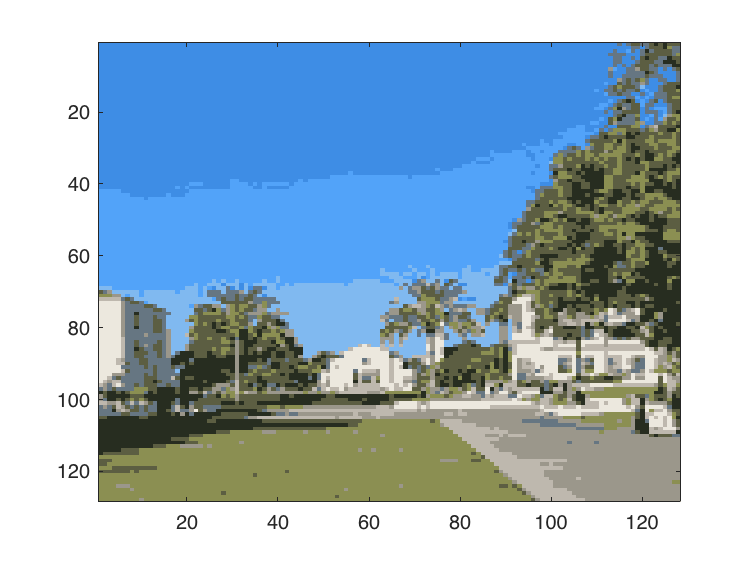


%display image
imagesc(A)